% Adjust the value of e here
e = -0.729365;

init = [1, 0]; % Initial conditions psi(u=0), psi'(u=0)
uMax = 10; % Maximum value of u to solve for
uReport = uMax; % Value of u to report psi at


% ODE SOLVER
opts = odeset('RelTol',1e-12,'AbsTol',1e-12); % Accuracy
[u,soln] = ode45(@ourderivatives, [0 uMax], init, opts, e); % Solve the ODE

% PROBLEM OUTPUT
texte=num2str(e,12);
result=interp1(u,soln(:,1), uReport);
disp(['For e = ',texte,', psi(',num2str(uReport),') = ',num2str(result)])

For e = -0.729365, psi(10) = 0.017866


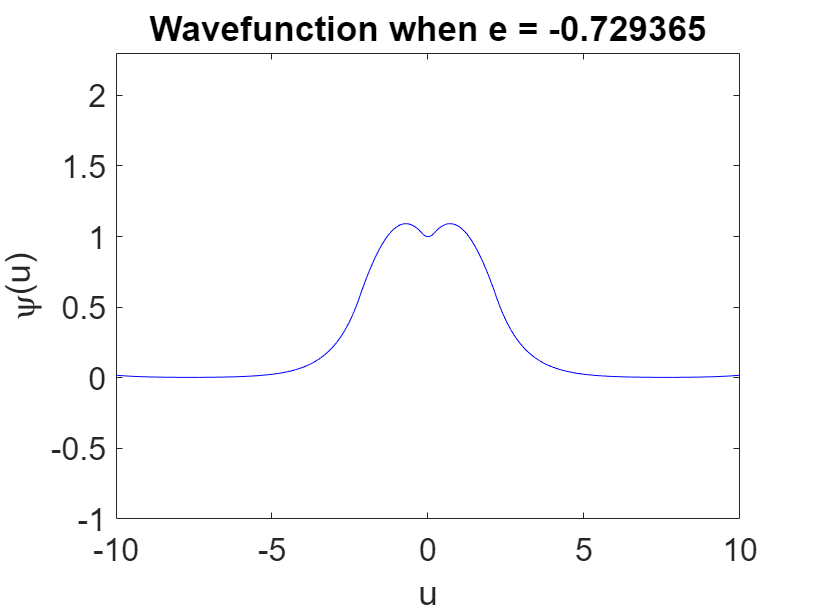

% Plot the solution, using its evenness to extend to negative u
p = plot(u,soln(:,1),'b',-u,soln(:,1),'b');
p(1).Parent.FontSize = 16;
axis([-uMax uMax -1 2.3])
xlabel('u');
ylabel('\psi(u)');
title(['Wavefunction when e = ',texte]);


% POTENTIAL
% Call this function as f(u)
% f(u) = 0 for abs(u) < gamma
% f(u) = -1 for gamma < abs(u) < 2 + gamma
% f(u) = 0 for abs(u) > 2 + gamma

function potential = f(u)
    gamma = 0.2;
    u1 = (abs(u) < gamma);    % |u| < gamma
    u2 = (abs(u) >= gamma & abs(u) <= 2 + gamma);    % in between
    u3 = (abs(u) > 2 + gamma);    % |u| > 2 + gamma
    potential(u1) = 0;
    potential(u2) = -1;
    potential(u3) = 0;
end

% ODE Definition - code your ODE here!!!
function derivatives = ourderivatives(u,psi,e)
    % psi(1) = psi(u), psi(2) = psi'(u)
    % derivatives = [psi'(u); psi''(u)]
    derivatives = [psi(2); 1.7403*psi(1)*(f(u)-e)];
end
